clear all;
clc;
close all;
disp('Iris Eting 209027333')

Iris Eting 209027333


disp('Nadav Orenstein 312349509')

Nadav Orenstein 312349509


(1) when we insert Nadav's 9 digit ID string to the attached function, this is what we get 

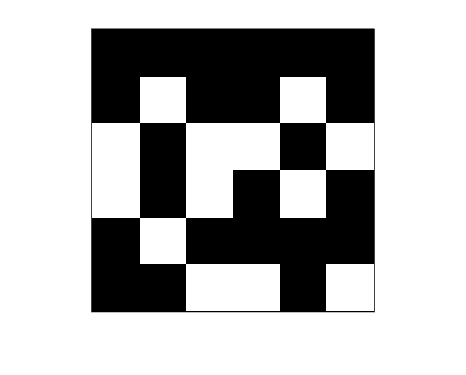

%% 2 - QR code reader
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
id = '312349509';
figure();
ID2QR(id);

(2) we printed it and took three photos of the QR code from three different angles and labled them according to the shooting angle: easy, intermediate and hard. 

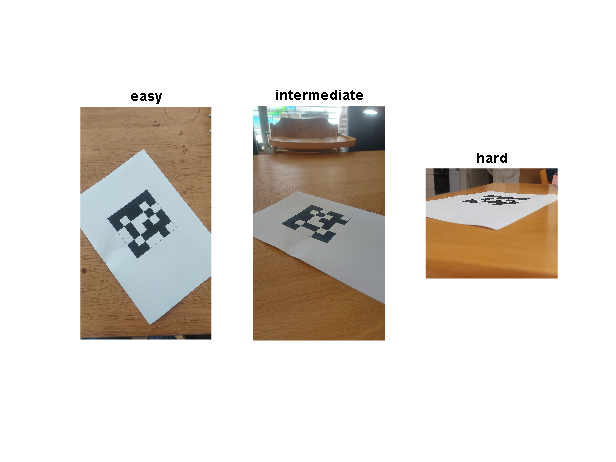

%%
qr_easy = imread("easy.jpg");
qr_inter = imread("med1.jpg");
qr_hard = imread("hard.jpg");
figure();
subplot(1,3,1);imshow(qr_easy);title('easy');
subplot(1,3,2);imshow(qr_inter);title('intermediate');
subplot(1,3,3);imshow(qr_hard);title('hard');

(3) We located the points on the QR code in each image manually... what a way to pick corners. 

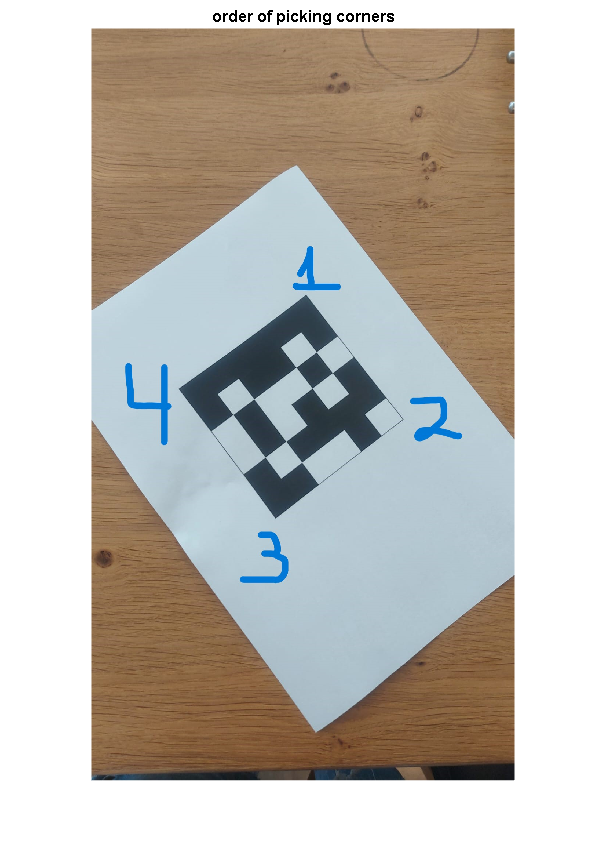

way = imread("way_to_pic_corners.jpg");
figure();
imshow(way); title('order of picking corners');

%% DO NOT DELETE THESE 3 COMMENT SECTIONS - ITS THE WAY WE GOT THE CORNERS MANUALLY
%figure();imshow(qr_easy);title('easy');
%[easy_x, easy_y] = ginput(4);
%hold on; scatter(easy_x, easy_y,'filled', 'o','LineWidth',1);
%easy_corners = [easy_x, easy_y];
%save('easy_corners.mat','easy_corners');

%figure();imshow(qr_inter);title('intermediate');
%[inter_x, inter_y] = ginput(4);
%hold on; scatter(inter_x, inter_y,'filled', 'o','LineWidth',1);
%inter_corners = [inter_x, inter_y];
%save('inter_corners.mat','inter_corners');

%figure();imshow(qr_hard);title('hard');
%[hard_x, hard_y] = ginput(4);
%hold on; scatter(hard_x, hard_y,'filled', 'o','LineWidth',1);
%hard_corners = [hard_x, hard_y];
%save('hard_corners.mat','hard_corners');

pic_easy_mat = importdata('easy_corners.mat');
pic_med_mat = importdata('inter_corners.mat');
pic_hard_mat = importdata('hard_corners.mat');

## (4) transformations

here we transform the image such that the QR code is straightened. For each image all three transformations we learned in class are applied: 

- Rigid (rotation, translation and scale transformation), 

- Affine (shearing added), 

- Perspective. 

here is the code for the transformations function:

%Iris Eting 209027333
%Nadav Orenstein 312349509

function [si1, si2, si3] = dip_straight_image(image, corners)
    % Define a set of fixed points for transformation
    fixedPoints = [1 1; 1 258; 258 258; 258 1];

    % Perform rigid transformation (similarity) and warp the image
    tform_rigid = fitgeotform2d(corners, fixedPoints, 'similarity');
    si1_LR = imwarp(image, tform_rigid, 'OutputView', imref2d([258 258]));
    si1 = fliplr(si1_LR);

    % Perform affine transformation and warp the image
    tform_affine = fitgeotform2d(corners, fixedPoints, 'affine');
    si2_LR = imwarp(image, tform_affine, 'OutputView', imref2d([258 258]));
    si2 = fliplr(si2_LR);

    % Perform perspective transformation and warp the image
    tform_perspective = fitgeotform2d(corners, fixedPoints, 'projective');
    si3_LR = imwarp(image, tform_perspective, 'OutputView', imref2d([258 258]));
    si3 = fliplr(si3_LR);

    % Display the results in a 1x3 subplot
    figure();
    subplot(1, 3, 1); imshow(si1); title('Rigid');
    subplot(1, 3, 2); imshow(si2); title('Affine');
    subplot(1, 3, 3); imshow(si3); title('Perspective');
end

Easy


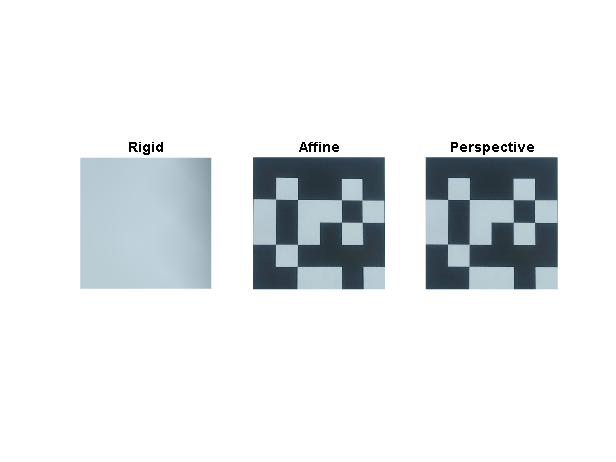

disp('Easy');

[easy_str_1, easy_str_2, easy_str_3] = dip_striaght_image(qr_easy, pic_easy_mat);

Med


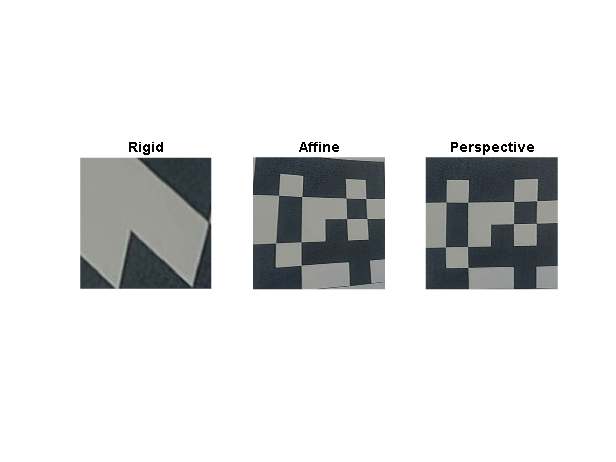

disp('Med');

[inter_str_1, inter_str_2, inter_str_3] = dip_striaght_image(qr_inter, pic_med_mat);

Hard


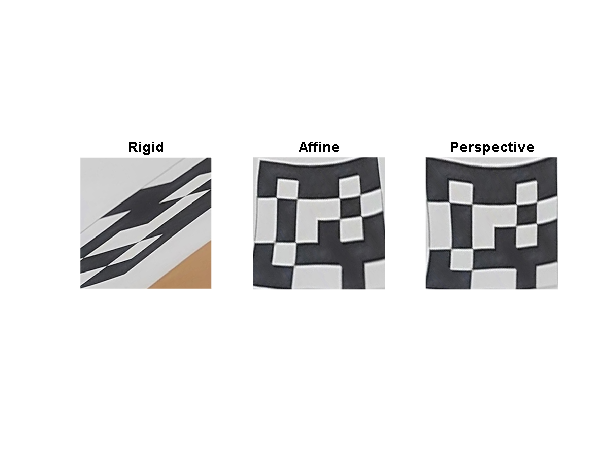

disp('Hard');

[hard_str_1, hard_str_2, hard_str_3] = dip_striaght_image(qr_hard, pic_hard_mat);

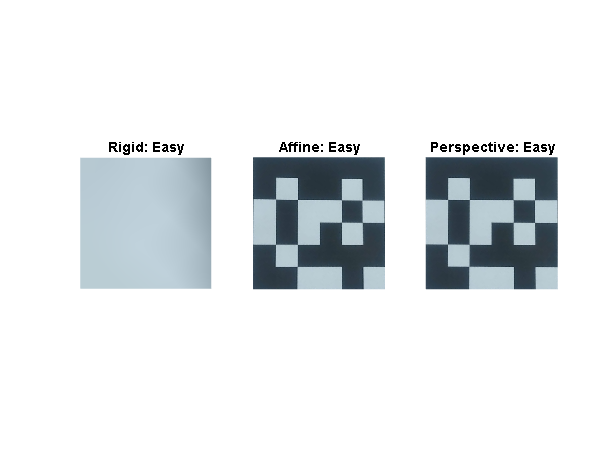

% Display the results in a 1x3 subplot and save them
fig = figure();
subplot(1, 3, 1); imshow(easy_str_1); title('Rigid: Easy');
subplot(1, 3, 2); imshow(easy_str_2); title('Affine: Easy');
subplot(1, 3, 3); imshow(easy_str_3); title('Perspective: Easy');

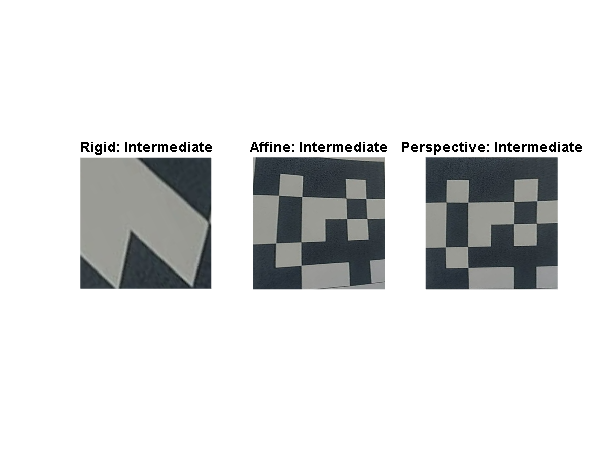

saveas(fig,'ex2 Easy transforms.jpeg');

fig = figure();
subplot(1, 3, 1); imshow(inter_str_1); title('Rigid: Intermediate');
subplot(1, 3, 2); imshow(inter_str_2); title('Affine: Intermediate');
subplot(1, 3, 3); imshow(inter_str_3); title('Perspective: Intermediate');

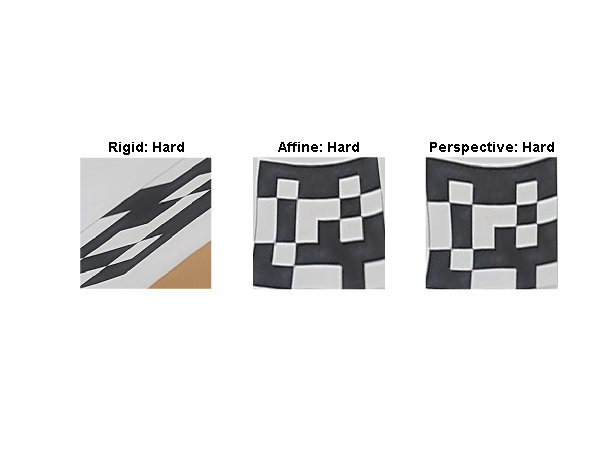

saveas(fig,'ex2 intermediate transforms.jpeg');

fig = figure();
subplot(1, 3, 1); imshow(hard_str_1); title('Rigid: Hard');
subplot(1, 3, 2); imshow(hard_str_2); title('Affine: Hard');
subplot(1, 3, 3); imshow(hard_str_3); title('Perspective: Hard');

saveas(fig,'ex2 Hard transforms.jpeg');

#### (5) results

#### (6) Extractig the binary values from the straightened QR

first, we calculate block size for our main block processing loop, by deviding the image to 36 regions. we are looking at the image as a 6x6 grid of blocks, where each block represents 1 bit.

in the main loop - for each block $b_{i,j} \;,i,j\in \left\lbrack 1,6\right\rbrack$ we decide weather it represents a 0 or a 1 by measuring average intensity. if it passes a treshold (140), it is decides that it represents a binary $1$, else, we get a binary $0$.

 this way, we get a binary array with the representation of the image's encoded bits.

#### (7) converting the binary array to decimals

After that, we loop through all the bits in groups of four and convert them to digits. for each 4 pixels $d_i ,d_{i+1} ,d_{i+2} ,d_{i+3} \;\forall i\le \frac{N}{4}-1$ we extract the decimal value of those 4 bits in order. each can represent togerther any digit $\in \left\lbrack 0,9\right\rbrack$

here is the code for the QR decoder function:

% Decode QR Code
% Iris Eting 209027333
% Nadav Orenstein 312349509

function output = decode_QR(img)
    
    % Convert the input RGB image to grayscale
    I = rgb2gray(img);
    
    % Convert the image to double precision
    I = im2double(I);
    
    % Normalize the pixel values to the range [0, 255]
    I_min = min(I(:));
    I_max = max(I(:));
    img = ((I - I_min) / (I_max - I_min)) * 255;
    
    % Input img of size 258*258 - each column represents 6 binary digits
    % Output: str
    % Define the length of the ID (4 binary digits * number of expected digits)
    id_length = 4 * 9;
    
    % Set a threshold for binary conversion
    threshold = 140;
    
    % Initialize binary array to store binary values
    binary_array = ones(1, id_length);
    
    % Calculate block size for processing
    block_size = size(img, 1) / 6; 
    
    % Counter for binary array
    n = 1;
    
    % Loop through the 6x6 blocks
    for i = 1:6
        for j = 1:6
            % Extract the current block
            block = img(((j - 1) * block_size + 1):(j * block_size),((i - 1) * block_size + 1):(i * block_size));
            
            % Calculate the average intensity of the block
            avg = mean(block, 'all');
            
            % Determine binary value based on the average intensity
            if avg > threshold
                binary_array(n) = 1;
            else
                binary_array(n) = 0;
            end
            
            % Increment counter
            n = n + 1;
        end
    end
    
    % Initialize output array
    output = zeros(1, 9);
    
    % Convert binary values to decimal and store in the output array
    for k = 1:9
        str_k = num2str(binary_array(((k - 1) * 4 + 1): k * 4));
        output(k) = bin2dec(str_k);
    end
end


here are the results


disp('Nadav Orenstein 312349509')
easy_id = decode_QR(easy_str_3)
disp('Nadav Orenstein 312349509')
Med_id = decode_QR(inter_str_3)

Nadav Orenstein 312349509


disp('Nadav Orenstein 312349509')

easy_id =      3     1     2     3     4     9     5     0     9


Hard_id = decode_QR(hard_str_3)

Nadav Orenstein 312349509


Med_id =      3     1     2     3     4     9     5     0     9


Nadav Orenstein 312349509


Hard_id =      3     1     2     3     4     9     5     0     9
